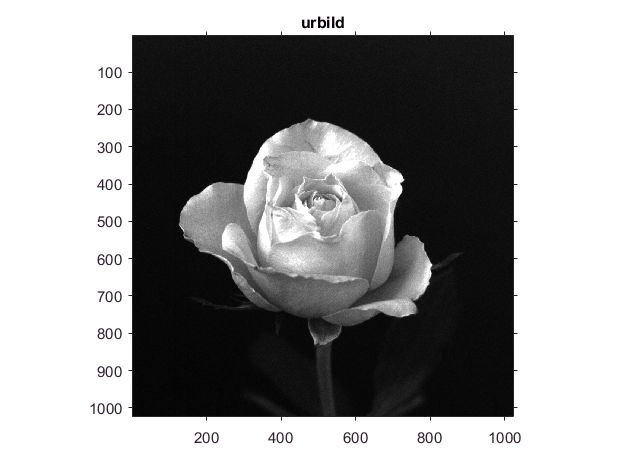

bild=im2double(imread('rose.tif'));

imshow(bild);
title('urbild'); figure;

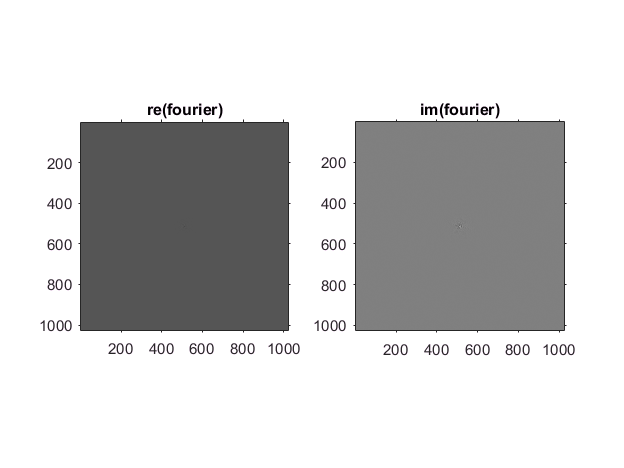


[H, B]=size(bild);
fourier=centerImage(fft2(bild)/numel(bild));

imshowCompl(fourier,'fourier');

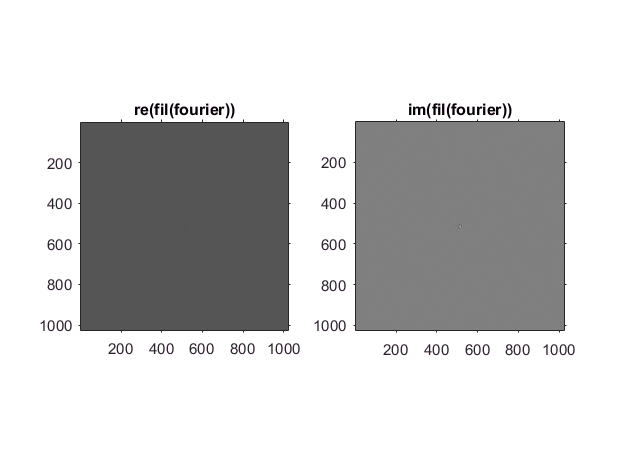


wert=10;
t=ones(H,B);
for j=wert:(H-wert)
    for k=wert:(B-wert)
        if j*j+k*k <= wert
            fourier(j, k)=0;
            t(j,k)=0;
        end
    end
end
imshow(t);
title('t');

imshowCompl(fourier, 'fil(fourier)');


Ifourier = ifft2(fourier);


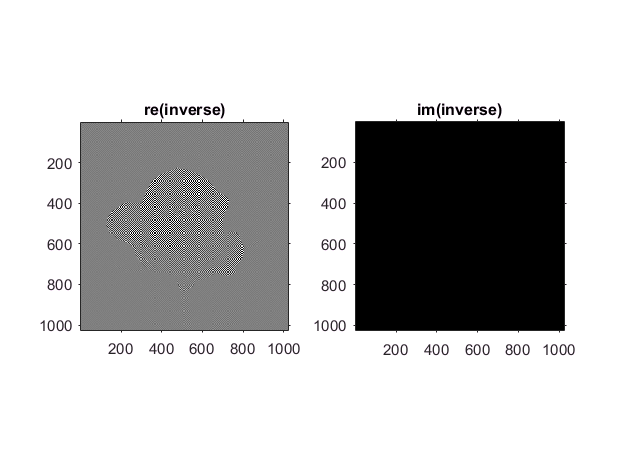

imshowCompl(Ifourier,'inverse');

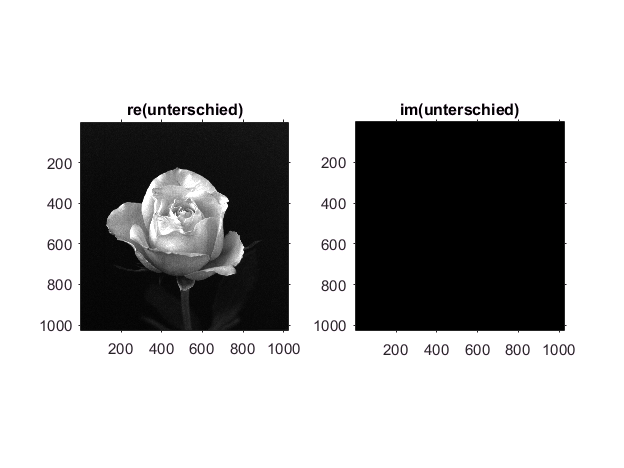

title('inverse fourier');

imshow(abs(Ifourier),[]);
title('abs(inverse)');

unterschied = bild - Ifourier;
imshowCompl(unterschied,'unterschied');